Exercise 1

Archimede's quadrature for the area under a parabola

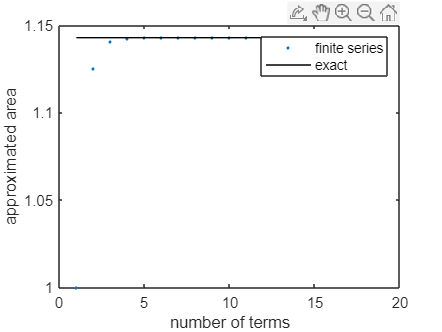

a = 1.0;
r = 0.125;
indices = 1:20 - 1;
exact = a ./ (1.0-r);

area = zeros(length(indices),1);
area(1) = a;
for i = indices(2:end)
    area(i) = area(i-1) + a .* r.^(i-1);
end

figure
plot(indices, area, ".");
hold on
plot(indices, ones(length(indices))*exact, 'k-');
xlabel("number of terms");
ylabel("approximated area");
legend("finite series", "exact");


disp("Area under parabola: " + area(end))

Area under parabola: 1.1429


Exercise 2

Exact value of $\int_0^3\sqrt{x+1}dx$

x0 = 0;
x1 = 3;
i0 = (x0+1).^1.5 / 1.5;
i1 = (x1+1).^1.5 / 1.5;
i_exact = i1 - i0;
disp("Integral (analytical): " + i_exact)

Integral (analytical): 4.6667


i_builtin = integral(@(x)sqrt(x+1), 0, 3);
disp("Integral (built-in): " + i_builtin)

Integral (built-in): 4.6667


Exercise 3

Left and right Riemann sums

fun = @(x) sqrt(x+1);
%fun = @(x) (1-x).^2;
a = 0;
b = 3;
N = 10;
dx = (b-a)/N;
exact = integral(fun, a, b);

% left
xl = a + dx * (0:N-1);
fxdxl = fun(xl)*dx;
il = sum(fxdxl);
fprintf("Left Riemann sum: %.4f (%.4f)\n", il, il-exact)

Left Riemann sum: 4.5148 (-0.1519)



% right
xr = a + dx * (1:N);
fxdxr = fun(xr)*dx;
ir = sum(fxdxr);
fprintf("Right Riemann sum: %.4f (%.4f)\n", ir, ir-exact)

Right Riemann sum: 4.8148 (0.1481)



% average of left and right
fxdxa = 0.5*(fxdxl + fxdxr);
ia = 0.5 * (il + ir);
fprintf("Mean of left and right: %.4f (%.4f)\n", ia, ia-exact)

Mean of left and right: 4.6648 (-0.0019)



% middle
xm = 0.5*(xl+xr);
fxdxm = fun(xm)*dx;
im = sum(fxdxm);
fprintf("Middle Riemann sum: %.4f (%.4f)\n", im, im-exact)

Middle Riemann sum: 4.6676 (0.0009)


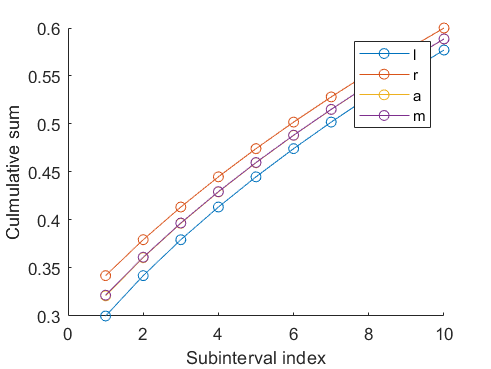


% plot
figure
hold on
plot(fxdxl, 'o-')
plot(fxdxr, 'o-')
plot(fxdxa, 'o-')
plot(fxdxm, 'o-')
legend("l", "r", "a", "m")
xlabel("Subinterval index")
ylabel("Culmulative sum")


$$f(a+h) = f(a) + f'(a)h + \frac{1}{2} f''(a) h^2 + O(h^3)$$



$$\int_{a}^{a+h} f(x) dx \approx f(a)h + \frac{1}{2}f'(a)h^2 + \frac{1}{6}f''(a) h^3$$


Left Riemann sum in a small interval $[a,a+h]$: $f(a)h$, the error is $-\frac{1}{2}f'(a)h^2 - \frac{1}{6}f''(a)h^3$;

Right Riemann sum in a small interval $[a,a+h]$: $f(a+h)h \approx f(a)h + f'(a)h^2 + \frac{1}{2} f''(a) h^3$, the error is $\frac{1}{2}f'(a)h^2 + \frac{1}{3} f''(a) h^3$;

Average of left and right Riemann sums: the error is $\frac{1}{12} f''(a) h^3$;

Middle Riemann sum: $f\left(a+\frac{1}{2}h \right) \approx f(a) h + f'(a) \frac{h}{2} h + \frac{1}{2} f''(a) \frac{h^2}{4} h$, the error is $-\frac{1}{24}f''(a)h^3$.

Plot changing $n$

fun = @(x) sqrt(x+1);
a = 0;
b = 3;
exact = integral(fun, a, b);

% integrals with changing n
n1 = 10;
n2 = 100;
ns = n1:n2;
ils = zeros(1, n2-n1+1);
irs = zeros(1, n2-n1+1);
ias = zeros(1, n2-n1+1);
ims = zeros(1, n2-n1+1);
for n = ns
    dx = (b-a)/n;
    il = sum(fun(a+dx*(0:n-1))*dx);
    ils(n-n1+1) = il;
    ir = sum(fun(a+dx*(1:n))*dx);
    irs(n-n1+1) = ir;
    ias(n-n1+1) = 0.5*(il+ir);
    im = sum(fun(a+dx*((1:n)-0.5))*dx);
    ims(n-n1+1) = im;
end

Expected on a linear scale:

- left and right approach exact from opposite sides

- average and middle are much closer to the exact

- middle has about half the error as average but approaches exact from an opposite side

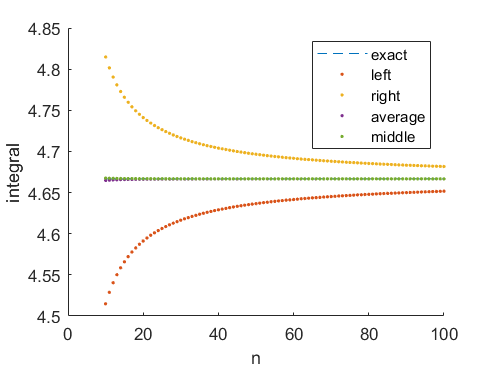

% plot linear
figure
hold on
plot(ns, exact*ns./ns, '--');
plot(ns, ils, '.');
plot(ns, irs, '.');
plot(ns, ias, '.');
plot(ns, ims, '.');
legend("exact", "left", "right", "average", "middle");
xlabel("n");
ylabel("integral");

Expected on a logarithmic absolute error scale:

- all four curves are linear when $n$ is large

- the slope of average and middle are twice as large as the slope of left and right

- left and right are close to each other

- middle looks like average translated downwards

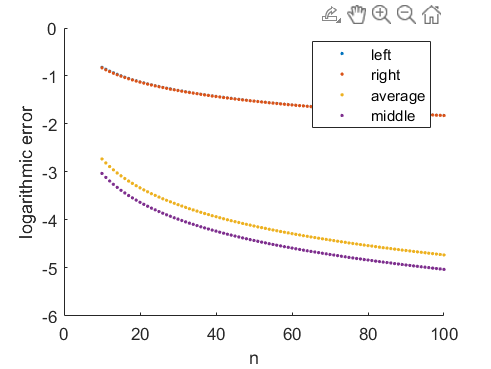

% plot logarithmic
figure
hold on
plot(ns, log10(abs(ils-exact)), '.');
plot(ns, log10(abs(irs-exact)), '.');
plot(ns, log10(abs(ias-exact)), '.');
plot(ns, log10(abs(ims-exact)), '.');
legend("left", "right", "average", "middle");
xlabel("n");
ylabel("logarithmic error");